# **SIMONE VICENTINI - PROGETTO PASSION IN ACTION 2022-2023**

clearvars
clc
close all

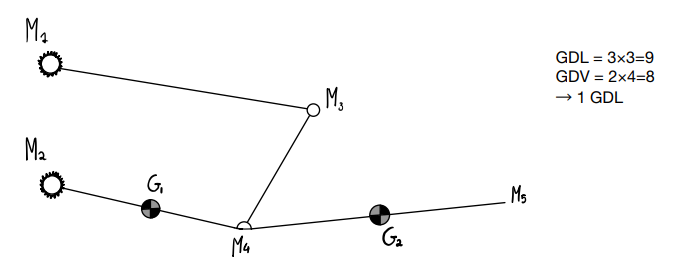

## OPERAZIONI PRELIMINARI

INPUT NECESSARI PER L'ANALISI


ultimacifracodicepersona=6;
penultimacifracodicepersona=7;
frequenza=20; %[Hz]
altezza=1.67; %[m]
peso=60+ultimacifracodicepersona; %[kg]
altezza2=1.90; %[m]
peso2=90; %[kg]
g=9.81; %[m/s^2]
vettoreg=[0; 9.61; 0]; %[m/s^2]
linktolerance=1.20; %[-], moltiplicare per il peso di braccio e avambraccio per tener conto della presenza del link
k=1e7/(penultimacifracodicepersona+1); %[N/m]
A=0.005; %[m]
W=penultimacifracodicepersona*1000; %[rad/s]

IMPORT DATI IN BASE AL CODICE PERSONA INSERITO


switch ultimacifracodicepersona
    case 1
        dati=load('data_stud.mat').uno;
    case 2
        dati=load('data_stud.mat').due;
    case 3
        dati=load('data_stud.mat').tre;
    case 4
        dati=load('data_stud.mat').quattro;
    case 5
        dati=load('data_stud.mat').cinque;
    case 6
        dati=load('data_stud.mat').sei;
    case 7
        dati=load('data_stud.mat').sette;
    case 8
        dati=load('data_stud.mat').otto;
    case 9
        dati=load('data_stud.mat').nove;
    case 0
        dati=load('data_stud.mat').zero;
end


CATALOGAZIONE DEI DATI IMPORTATI


xM1=dati(:,1)./1000; %[m]
yM1=dati(:,2)./1000; %[m]
xM3=dati(:,3)./1000; %[m]
yM3=dati(:,4)./1000; %[m]
xM4=dati(:,5)./1000; %[m]
yM4=dati(:,6)./1000; %[m]
xM5=dati(:,7)./1000; %[m]
yM5=dati(:,8)./1000; %[m]


CREAZIONE DI UN VETTORE TEMPO (0-tfinale)


dt=1/frequenza;
tfinale=(size(dati,1)*dt)-dt;
t=0:dt:tfinale;
%(tolto un dt in tfinale poichè si parte da t=0)


DATI DERIVATI DALLE TABELLE ANTROPOMETRICHE


coefficientebaricentrobraccioprossimale=0.436; %[-]
coefficientebaricentroavambraccioprossimale=0.430; %[-]
coefficientebaricentroavambracciodistale=0.570; %[-]
coefficientebaricentroavambracciomanoprossimale=0.682; %[-]
coefficientemassamano=0.006; %[-]
coefficientemassabraccio=0.028; %[-]
coefficientemassaavambraccio=0.016; %[-]
coefficienterogbraccio=0.322; %[-]
coefficienterogavambracciomano=0.468; %[-]
coefficientelunghezzabraccio=0.186; %[-]
coefficientelunghezzaavambracci0=0.146; %[-]


## **---- ANALISI CINEMATICA----**

### 3.1 CALCOLO DELLA STORIA TEMPORALE DEL MARKER 2 (xM2=xM1, yM2=yM1-0.088 m)

xM2=xM1;
yM2=yM1-0.088*ones(size(yM1,1),1);


### 3.2 CALCOLO DELLE LUNGHEZZE M1-M2, M1-M3, M2-M4, M3-M4

lunghezzaM1M2=(((xM2-xM1).^2+(yM2-yM1).^2).^(1/2)); %[m]
lunghezzaM1M3=(((xM3-xM1).^2+(yM3-yM1).^2).^(1/2)); %[m]
lunghezzaM2M4=(((xM4-xM2).^2+(yM4-yM2).^2).^(1/2)); %[m]
lunghezzaM3M4=(((xM4-xM3).^2+(yM4-yM3).^2).^(1/2)); %[m]
lunghezzaM4M5=(((xM5-xM4).^2+(yM5-yM4).^2).^(1/2)); %[m]
%CALCOLO DELLE LUNGHEZZE MEDIE
lunghezzaM1M2media=mean(lunghezzaM1M2); %[m]
lunghezzaM1M3media=mean(lunghezzaM1M3); %[m]
lunghezzaM2M4media=mean(lunghezzaM2M4); %[m]
lunghezzaM3M4media=mean(lunghezzaM3M4); %[m]
lunghezzaM4M5media=mean(lunghezzaM4M5); %[m]


### 3.3 RAPPRESENTAZIONE GRAFICA DELLA TRAIETTORIA DEI PUNTI

1-GRAFICI DELLE COORDINATE IN FUNZIONE DEL TEMPO

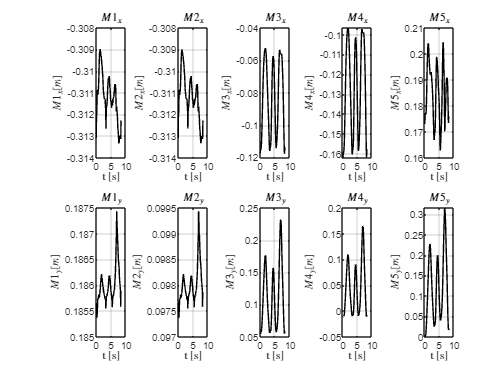

figure
%xM1
subplot(251)
plot(t,xM1,'k')
grid on
title('$M1_{x}$', 'Interpreter', 'latex')
ylabel('$M1_{x} [m]$', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
%xM2
subplot(252)
plot(t,xM2,'k')
grid on
title('$M2_{x}$', 'Interpreter', 'latex')
ylabel('$M2_{x} [m]$', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
%xM3
subplot(253)
plot(t,xM3,'k')
grid on
title('$M3_{x}$', 'Interpreter', 'latex')
ylabel('$M3_{x} [m]$', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
%xM4
subplot(254)
plot(t,xM4,'k')
grid on
title('$M4_{x}$', 'Interpreter', 'latex')
ylabel('$M4_{x} [m]$', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
%xM5
subplot(255)
plot(t,xM5,'k')
grid on
title('$M5_{x}$', 'Interpreter', 'latex')
ylabel('$M5_{x} [m]$', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
%yM1
subplot(256)
plot(t,yM1,'k')
grid on
title('$M1_{y}$', 'Interpreter', 'latex')
ylabel('$M1_{y} [m]$', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
%yM2
subplot(257)
plot(t,yM2,'k')
grid on
title('$M2_{y}$', 'Interpreter', 'latex')
ylabel('$M2_{y} [m]$', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
%yM3
subplot(258)
plot(t,yM3,'k')
grid on
title('$M3_{y}$', 'Interpreter', 'latex')
ylabel('$M3_{y} [m]$', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
%yM4
subplot(259)
plot(t,yM4,'k')
grid on
title('$M4_{y}$', 'Interpreter', 'latex')
ylabel('$M4_{y} [m]$', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
%xM5
subplot(2,5,10)
plot(t,yM5,'k')
grid on
title('$M5_{y}$', 'Interpreter', 'latex')
ylabel('$M5_{y} [m]$', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')

2-GRAFICI DELLA TRAIETTORIA

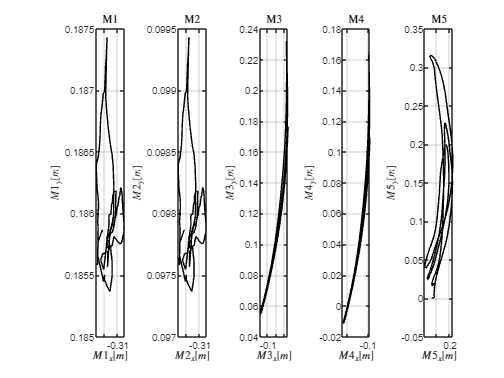

figure
%M1
subplot(151)
plot(xM1,yM1,'k')
grid on
title('M1', 'Interpreter', 'latex')
xlabel('$M1_{x} [m]$', 'Interpreter', 'latex')
ylabel('$M1_{y} [m]$', 'Interpreter', 'latex')
%M2
subplot(152)
plot(xM2,yM2,'k')
grid on
title('M2', 'Interpreter', 'latex')
xlabel('$M2_{x} [m]$', 'Interpreter', 'latex')
ylabel('$M2_{y} [m]$', 'Interpreter', 'latex')
%M3
subplot(153)
plot(xM3,yM3,'k')
grid on
title('M3', 'Interpreter', 'latex')
xlabel('$M3_{x} [m]$', 'Interpreter', 'latex')
ylabel('$M3_{y} [m]$', 'Interpreter', 'latex')
%M4
subplot(154)
plot(xM4,yM4,'k')
grid on
title('M4', 'Interpreter', 'latex')
xlabel('$M4_{x} [m]$', 'Interpreter', 'latex')
ylabel('$M4_{y} [m]$', 'Interpreter', 'latex')
%M5
subplot(155)
plot(xM5,yM5,'k')
grid on
title('M5', 'Interpreter', 'latex')
xlabel('$M5_{x} [m]$', 'Interpreter', 'latex')
ylabel('$M5_{y} [m]$', 'Interpreter', 'latex')

### 3.4 CALCOLO DELLE POSIZIONI DEI BARICENTRI G1 E G2 E TRACCIAMENTO DELLE LORO TRAIETTORIE

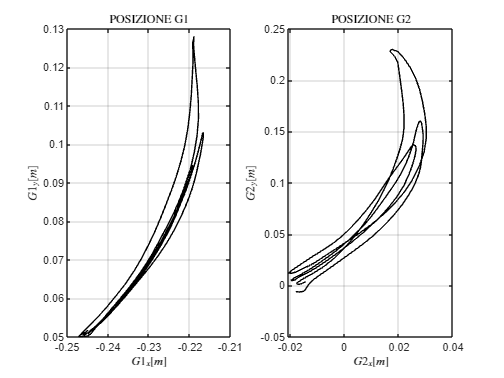

%LUNGHEZZE ARTICOLAZIONE-BARICENTRO
lunghezzaM2G1=(coefficientebaricentrobraccioprossimale.*lunghezzaM2M4); %[m]
lunghezzaM4G2=(coefficientebaricentroavambraccioprossimale.*lunghezzaM4M5); %[m]
lunghezzaM5G2=(coefficientebaricentroavambracciodistale.*lunghezzaM4M5); %[m]
lunghezzaM2G1media=mean(lunghezzaM2G1); %[m]
lunghezzaM4G2media=mean(lunghezzaM4G2); %[m]
lunghezzaM5G2media=mean(lunghezzaM5G2); %[m]

%CALCOLO ANGOLI (necessari per calcolare le posizioni dei baricentri)
angoloM1M2=(pi/2)*ones(size(t,2),1); %[rad]
angoloM1M3=atan((yM3-yM1)./(xM3-xM1)); %[rad]
angoloM2M4=atan((yM4-yM2)./(xM4-xM2)); %[rad]
angoloM3M4=pi*ones(size(t,2),1)+atan((yM4-yM3)./(xM4-xM3)); %[rad]
angoloM4M5=atan((yM5-yM4)./(xM5-xM4)); %[rad]

%CALCOLO DELLE COORDINATE DEI BARICENTRI
xG1=zeros(size(t,2),1); %[m]
yG1=zeros(size(t,2),1); %[m]
xG2=zeros(size(t,2),1); %[m]
yG2=zeros(size(t,2),1); %[m]
xG2M5=zeros(size(t,2),1); %[m]
yG2M5=zeros(size(t,2),1); %[m]
for jj=1:(size(t,2))
    xG1(jj,1)=xM2(jj,1)+cos(angoloM2M4(jj,1))*lunghezzaM2G1(jj,1); %[m]
    yG1(jj,1)=yM2(jj,1)+sin(angoloM2M4(jj,1))*lunghezzaM2G1(jj,1); %[m]
    xG2(jj,1)=xM4(jj,1)+cos(angoloM4M5(jj,1))*lunghezzaM4G2(jj,1); %[m]
    yG2(jj,1)=yM4(jj,1)+sin(angoloM4M5(jj,1))*lunghezzaM4G2(jj,1); %[m]
    xG2M5(jj,1)=xM5(jj,1)-cos(angoloM4M5(jj,1))*lunghezzaM5G2(jj,1); %[m]
    yG2M5(jj,1)=yM5(jj,1)-sin(angoloM4M5(jj,1))*lunghezzaM5G2(jj,1); %[m]
end

%RAPPRESENTAZIONE GRAFICA DELLE TRAIETTORIE DEI BARICENTRI
figure
subplot(121)
plot(xG1,yG1, 'k')
grid on
title('POSIZIONE G1', 'Interpreter', 'latex')
xlabel('$G1_{x} [m]$', 'Interpreter', 'latex')
ylabel('$G1_{y} [m]$', 'Interpreter', 'latex')
subplot(122)
plot(xG2,yG2, 'k')
grid on
title('POSIZIONE G2', 'Interpreter', 'latex')
xlabel('$G2_{x} [m]$', 'Interpreter', 'latex')
ylabel('$G2_{y} [m]$', 'Interpreter', 'latex')

### 3.5 CALCOLO DELL'ESCURSIONE ANGOLARE DELLA SPALLA (ROM)

escursionespalla=max(angoloM2M4)-min(angoloM2M4); %[rad]
disp(append('L''escursione angolare della spalla è ', num2str(rad2deg(escursionespalla)), '°'));

L'escursione angolare della spalla è 53.0202°


### 3.6 CALCOLO DELLE STORIE TEMPORALI DI VELOCITA' E ACCELERAZIONE DEL PUNTO M4

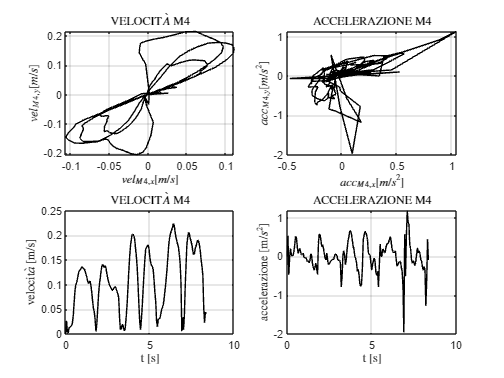

xvelocitaM4=zeros(size(t,2),1); %[m/s]
yvelocitaM4=zeros(size(t,2),1); %[m/s]
xaccelerazioneM4=zeros(size(t,2),1); %[m/s^2]
yaccelerazioneM4=zeros(size(t,2),1); %[m/s^2]
velocitaM4=zeros(size(t,2),1); %[m/s]
accelerazioneM4=zeros(size(t,2),1); %[m/s^2]

%assumo v0=0 e a0=0
xvelocitaM4(1,1)=0; %[m/s]
yvelocitaM4(1,1)=0; %[m/s]
xaccelerazioneM4(1,1)=0; %[m/s^2]
yaccelerazioneM4(1,1)=0; %[m/s^2]
velocitaM4(1,1)=0; %[m/s]
accelerazioneM4(1,1)=0; %[m/s^2]

%CALCOLO DELLE COMPONENTI DI VELOCITA' E ACCELERAZIONE DI M4
for jj=2:size(t,2)
    xvelocitaM4(jj,1)=((xM4(jj,1)-xM4(jj-1,1))/dt); %[m/s]
    yvelocitaM4(jj,1)=((yM4(jj,1)-yM4(jj-1,1))/dt); %[m/s]
end
for jj=2:size(t,2)
    xaccelerazioneM4(jj,1)=((xvelocitaM4(jj,1)-xvelocitaM4(jj-1,1))/dt); %[m/s^2]
    yaccelerazioneM4(jj,1)=((yvelocitaM4(jj,1)-yvelocitaM4(jj-1,1))/dt); %[m/s^2]
end

%CALCOLO DEI MODULI DI VELOCITA' E ACCELERAZIONE DI M4
for jj=2:size(t,2)
    velocitaM4(jj,1)=(sqrt(((xM4(jj,1)-xM4(jj-1,1))^2)+(((yM4(jj,1))-yM4(jj-1,1))^2)))/dt; %[m/s]
end
for jj=2:size(t,2)
    accelerazioneM4(jj,1)=(velocitaM4(jj,1)-velocitaM4(jj-1,1))/dt; %[m/s^2]
end

figure
subplot(221)
plot(xvelocitaM4,yvelocitaM4, 'k')
grid on
title('VELOCIT$\grave{A}$ M4', 'Interpreter', 'latex')
xlabel('$vel_{M4,x} [m/s]$', 'Interpreter', 'latex')
ylabel('$vel_{M4,y} [m/s]$', 'Interpreter', 'latex')
subplot(222)
plot(xaccelerazioneM4,yaccelerazioneM4, 'k')
grid on
title('ACCELERAZIONE M4', 'Interpreter', 'latex')
xlabel('$acc_{M4,x} [m/s^2]$', 'Interpreter', 'latex')
ylabel('$acc_{M4,y} [m/s^2]$', 'Interpreter', 'latex')
subplot(223)
plot(t,velocitaM4,'k')
grid on
title('VELOCIT$\grave{A}$ M4', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
ylabel('velocit$\grave{a}$ [m/s]', 'Interpreter', 'latex')
subplot(224)
plot(t,accelerazioneM4, 'k')
grid on
title('ACCELERAZIONE M4', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
ylabel('accelerazione [m/$s^2$]', 'Interpreter', 'latex')

### 3.7 CALCOLO DELLE STORIE TEMPORALI DI VELOCITA' E ACCELERAZIONE ANGOLARE DI M3 E M5

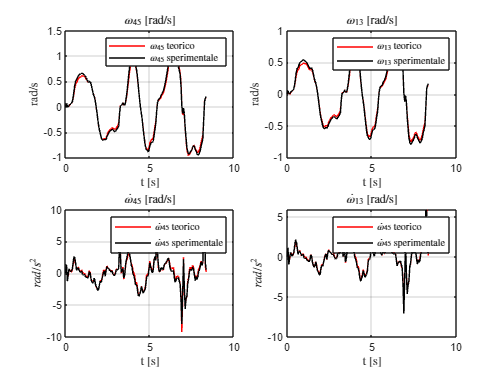

%con una chiusura cinematica triangolare trovo la velocità angolare
%dell'asta M2M4 teorica (pongo omega24(0)=0):
omega24teorico=zeros(size(t,2),1); %[rad/s]
omega24teorico(1,1)=0; %[rad/s]
omega24puntoteorico=zeros(size(t,2),1); %[rad/s^2]
omega24puntoteorico(1,1)=0; %[rad/s^2]
for jj=2:size(t,2)
    omega24teorico(jj,1)=yvelocitaM4(jj,1)/(lunghezzaM2M4(jj,1)*sin(angoloM2M4(jj,1)+pi/2)); %[rad/s]
    omega24puntoteorico(jj,1)=(yaccelerazioneM4(jj,1)-(omega24teorico(jj,1)^2)*lunghezzaM2M4(jj,1)*sin(angoloM2M4(jj,1)+pi))/(lunghezzaM2M4(jj,1)*sin(angoloM2M4(jj,1)+pi/2)); %[rad/s^2]
end
omega45teorico=omega24teorico; %[rad/s]
omega45puntoteorico=omega24puntoteorico; %[rad/s^2]

%con un'altra chiusura cinematica risolvo il quadrilatero articolato e
%trovo omega13 e omega13punto
omega13teorico=zeros(size(t,2),1); %[rad/s]
omega13teorico(1,1)=0; %[rad/s]
omega34teorico=zeros(size(t,2),1); %[rad/s]
omega34teorico(1,1)=0; %[rad/s]
omega13puntoteorico=zeros(size(t,2),1); %[rad/s^2]
omega13puntoteorico(1,1)=0; %[rad/s^2]
omega34puntoteorico=zeros(size(t,2),1); %[rad/s^2]
omega34puntoteorico(1,1)=0; %[rad/s^2]
for jj=2:size(t,2)
    V=[lunghezzaM1M3(jj,1)*cos(angoloM1M3(jj,1)) -lunghezzaM3M4(jj,1)*cos(angoloM3M4(jj,1)-pi);lunghezzaM1M3(jj,1)*sin(angoloM1M3(jj,1)) -lunghezzaM3M4(jj,1)*sin(angoloM3M4(jj,1)-pi)];
    solvel=V\[lunghezzaM2M4(jj,1)*omega24teorico(jj,1)*cos(angoloM2M4(jj,1)); lunghezzaM2M4(jj,1)*omega24teorico(jj,1)*sin(angoloM2M4(jj,1))]; %[rad/s]
    omega13teorico(jj,1)=solvel(1,1); %[rad/s]
    omega34teorico(jj,1)=solvel(2,1); %[rad/s]
    solacc=V\[lunghezzaM3M4(jj,1)*(omega34teorico(jj,1)^2)*cos(angoloM3M4(jj,1)-pi/2)-lunghezzaM1M3(jj,1)*(omega13teorico(jj,1)^2)*cos(angoloM1M3(jj,1)+pi/2)+lunghezzaM2M4(jj,1)*omega24puntoteorico(jj,1)*cos(angoloM2M4(jj,1))+lunghezzaM2M4(jj,1)*(omega24teorico(jj,1)^2)*cos(angoloM2M4(jj,1)+pi/2);
              lunghezzaM3M4(jj,1)*(omega34teorico(jj,1)^2)*sin(angoloM3M4(jj,1)-pi/2)-lunghezzaM1M3(jj,1)*(omega13teorico(jj,1)^2)*sin(angoloM1M3(jj,1)+pi/2)+lunghezzaM2M4(jj,1)*omega24puntoteorico(jj,1)*sin(angoloM2M4(jj,1))+lunghezzaM2M4(jj,1)*(omega24teorico(jj,1)^2)*sin(angoloM2M4(jj,1)+pi/2)]; %[rad/s^2]
    omega13puntoteorico(jj,1)=solacc(1,1); %[rad/s^2]
    omega34puntoteorico(jj,1)=solacc(2,1); %[rad/s^2]
end

%calcolo ora i valori sperimentali
omega24sperimentale=zeros(size(t,2),1); %[rad/s]
omega24sperimentale(1,1)=0; %[rad/s]
omega13sperimentale=zeros(size(t,2),1); %[rad/s]
omega13sperimentale(1,1)=0; %[rad/s]
omega24puntosperimentale=zeros(size(t,2),1); %[rad/s^2]
omega24puntosperimentale(1,1)=0; %[rad/s^2]
omega13puntosperimentale=zeros(size(t,2),1); %[rad/s^2]
omega13puntosperimentale(1,1)=0; %[rad/s^2]
for jj=2:size(t,2)
    omega24sperimentale(jj,1)=(angoloM2M4(jj,1)-angoloM2M4(jj-1,1))/dt; %[rad/s]
    omega13sperimentale(jj,1)=(angoloM1M3(jj,1)-angoloM1M3(jj-1,1))/dt; %[rad/s]
    omega24puntosperimentale(jj,1)=(omega24sperimentale(jj,1)-omega24sperimentale(jj-1,1))/dt; %[rad/s^2]
    omega13puntosperimentale(jj,1)=(omega13sperimentale(jj,1)-omega13sperimentale(jj-1,1))/dt; %[rad/s^2]
end
omega45sperimentale=omega24sperimentale; %[rad/s]
omega45puntosperimentale=omega24puntosperimentale; %[rad/s^2]

%derivo inoltre velocità e accelerazione teoriche di M3 e M5, necessarie per lo
%svolgimento del successivo punto, con il teorema di Rivals
xvelocitaM3teorico=zeros(size(t,2),1); %[m/s]
yvelocitaM3teorico=zeros(size(t,2),1); %[m/s]
xvelocitaM3teorico(1,1)=0; %[m/s]
yvelocitaM3teorico(1,1)=0; %[m/s]
xaccelerazioneM3teorico=zeros(size(t,2),1); %[m/s^2]
yaccelerazioneM3teorico=zeros(size(t,2),1); %[m/s^2]
xaccelerazioneM3teorico(1,1)=0; %[m/s^2]
yaccelerazioneM3teorico(1,1)=0; %[m/s^2]
xvelocitaM5teorico=zeros(size(t,2),1); %[m/s]
yvelocitaM5teorico=zeros(size(t,2),1); %[m/s]
xvelocitaM5teorico(1,1)=0; %[m/s]
yvelocitaM5teorico(1,1)=0; %[m/s]
xaccelerazioneM5teorico=zeros(size(t,2),1); %[m/s^2]
yaccelerazioneM5teorico=zeros(size(t,2),1); %[m/s^2]
xaccelerazioneM5teorico(1,1)=0; %[m/s^2]
yaccelerazioneM5teorico(1,1)=0; %[m/s^2]
for jj=2:size(t,2)
    velocitaM4vettore=[xvelocitaM4(jj,1); yvelocitaM4(jj,1); 0]; %[m/s]
    accelerazioneM4vettore=[xaccelerazioneM4(jj,1); yaccelerazioneM4(jj,1); 0]; %[m/s^2]
    omega13teoricovettore=[0; 0; omega13teorico(jj,1)]; %[rad/s]
    omega24teoricovettore=[0; 0; omega24teorico(jj,1)]; %[rad/s]
    omega13puntoteoricovettore=[0; 0; omega13puntoteorico(jj,1)]; %[rad/s^2]
    omega24puntoteoricovettore=[0; 0; omega24puntoteorico(jj,1)]; %[rad/s^2]
    vettore3_1=[xM3(jj,1)-xM1(jj,1); yM3(jj,1)-yM1(jj,1); 0];
    vettore5_4=[xM5(jj,1)-xM4(jj,1); yM5(jj,1)-yM4(jj,1); 0];
    velocitaM3vettore=cross(omega13teoricovettore,vettore3_1); %[m/s]
    xvelocitaM3teorico(jj,1)=velocitaM3vettore(1,1); %[m/s]
    yvelocitaM3teorico(jj,1)=velocitaM3vettore(2,1); %[m/s]
    velocitaM5vettore=velocitaM4vettore+cross(omega24teoricovettore,vettore5_4); %[m/s]
    xvelocitaM5teorico(jj,1)=velocitaM5vettore(1,1); %[m/s]
    yvelocitaM5teorico(jj,1)=velocitaM5vettore(2,1); %[m/s]
    accelerazioneM3vettore=cross(omega13puntoteoricovettore,vettore3_1)-(omega13teorico(jj,1)^2)*vettore3_1; %[m/s^2]
    xaccelerazioneM3teorico(jj,1)=accelerazioneM3vettore(1,1); %[m/s^2]
    yaccelerazioneM3teorico(jj,1)=accelerazioneM3vettore(2,1); %[m/s^2]
    accelerazioneM5vettore=accelerazioneM4vettore+cross(omega24puntoteoricovettore,vettore5_4)-(omega24teorico(jj,1)^2)*vettore5_4; %[m/s^2]
    xaccelerazioneM5teorico(jj,1)=accelerazioneM5vettore(1,1); %[m/s^2]
    yaccelerazioneM5teorico(jj,1)=accelerazioneM5vettore(2,1); %[m/s^2]
end    
figure
subplot(221)
plot(t,omega45teorico, 'r')
grid on
title('${\omega}_{45}$ [rad/s]', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
ylabel('rad/s', 'Interpreter', 'latex')
hold on
plot(t,omega45sperimentale, 'k')
legend('${\omega}_{45}$ teorico','${\omega}_{45}$ sperimentale', 'Interpreter', 'latex')
subplot(222)
plot(t,omega13teorico, 'r')
grid on
title('${\omega}_{13}$ [rad/s]', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
ylabel('rad/s', 'Interpreter', 'latex')
hold on
plot(t,omega13sperimentale, 'k')
legend('${\omega}_{13}$ teorico','${\omega}_{13}$ sperimentale', 'Interpreter', 'latex')
subplot(223)
plot(t,omega45puntoteorico, 'r')
grid on
title('$\dot{\omega}_{45}$ [rad/s]', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
ylabel('$rad/s^2$', 'Interpreter', 'latex')
hold on
plot(t,omega45puntosperimentale, 'k')
legend('$\dot{\omega}_{45}$ teorico','$\dot{\omega}_{45}$ sperimentale', 'Interpreter', 'latex')
subplot(224)
plot(t,omega13puntoteorico, 'r')
grid on
title('$\dot{\omega}_{13}$ [rad/s]', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
ylabel('$rad/s^2$', 'Interpreter', 'latex')
hold on
plot(t,omega13puntosperimentale, 'k')
legend('$\dot{\omega}_{45}$ teorico','$\dot{\omega}_{45}$ sperimentale', 'Interpreter', 'latex')

### 3.8 CONFRONTO TRA I VALORI TEORICI E SPERIMENTALI DI VELOCITA' E ACCELERAZIONE DI M3 e M5

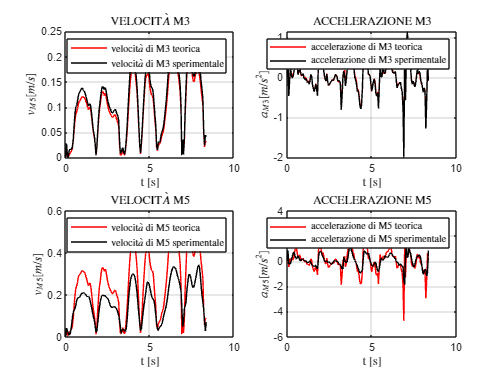

%RICAVO I VALORI SPERIMENTALI
xvelocitaM3sperimentale=zeros(size(t,2),1); %[m/s]
xvelocitaM3sperimentale(1,1)=0; %[m/s]
yvelocitaM3sperimentale=zeros(size(t,2),1); %[m/s]
yvelocitaM3sperimentale(1,1)=0; %[m/s]
xaccelerazioneM3sperimentale=zeros(size(t,2),1); %[m/s^2]
xaccelerazioneM3sperimentale(1,1)=0; %[m/s^2]
yaccelerazioneM3sperimentale=zeros(size(t,2),1); %[m/s^2]
yaccelerazioneM3sperimentale(1,1)=0; %[m/s^2]
xvelocitaM5sperimentale=zeros(size(t,2),1); %[m/s]
xvelocitaM5sperimentale(1,1)=0; %[m/s]
yvelocitaM5sperimentale=zeros(size(t,2),1); %[m/s]
yvelocitaM5sperimentale(1,1)=0; %[m/s]
xaccelerazioneM5sperimentale=zeros(size(t,2),1); %[m/s^2]
xaccelerazioneM5sperimentale(1,1)=0; %[m/s^2]
yaccelerazioneM5sperimentale=zeros(size(t,2),1); %[m/s^2]
yaccelerazioneM5sperimentale(1,1)=0; %[m/s^2]
for jj=2:size(t,2)
    xvelocitaM3sperimentale(jj,1)=((xM3(jj,1)-xM3(jj-1,1))/dt); %[m/s]
    yvelocitaM3sperimentale(jj,1)=((yM3(jj,1)-yM3(jj-1,1))/dt); %[m/s]
    xvelocitaM5sperimentale(jj,1)=((xM5(jj,1)-xM5(jj-1,1))/dt); %[m/s]
    yvelocitaM5sperimentale(jj,1)=((yM5(jj,1)-yM5(jj-1,1))/dt); %[m/s]
end
for jj=2:size(t,2)
    xaccelerazioneM3sperimentale(jj,1)=((xvelocitaM3sperimentale(jj,1)-xvelocitaM3sperimentale(jj-1,1))/dt); %[m/s^2]
    yaccelerazioneM3sperimentale(jj,1)=((yvelocitaM3sperimentale(jj,1)-yvelocitaM3sperimentale(jj-1,1))/dt); %[m/s^2]
    xaccelerazioneM5sperimentale(jj,1)=((xvelocitaM5sperimentale(jj,1)-xvelocitaM5sperimentale(jj-1,1))/dt); %[m/s^2]
    yaccelerazioneM5sperimentale(jj,1)=((yvelocitaM5sperimentale(jj,1)-yvelocitaM5sperimentale(jj-1,1))/dt); %[m/s^2]
end

%CALCOLO DEI MODULI DI VELOCITA' E ACCELERAZIONE DI M3 e M5
velocitaM3teorico=zeros(size(t,2),1); %[m/s]
velocitaM3teorico(1,1)=0; %[m/s]
velocitaM3sperimentale=zeros(size(t,2),1); %[m/s]
velocitaM3sperimentale(1,1)=0; %[m/s]
accelerazioneM3teorico=zeros(size(t,2),1); %[m/s^2]
accelerazioneM3teorico(1,1)=0; %[m/s^2]
accelerazioneM3sperimentale=zeros(size(t,2),1); %[m/s^2]
accelerazioneM3sperimentale(1,1)=0; %[m/s^2]
velocitaM5teorico=zeros(size(t,2),1); %[m/s]
velocitaM5teorico(1,1)=0; %[m/s]
velocitaM5sperimentale=zeros(size(t,2),1); %[m/s]
velocitaM5sperimentale(1,1)=0; %[m/s]
accelerazioneM5teorico=zeros(size(t,2),1); %[m/s^2]
accelerazioneM5teorico(1,1)=0; %[m/s^2]
accelerazioneM5sperimentale=zeros(size(t,2),1); %[m/s^2]
accelerazioneM5sperimentale(1,1)=0; %[m/s^2]
for jj=2:size(t,2)
    velocitaM3teorico(jj,1)=sqrt((xvelocitaM3teorico(jj,1)^2)+(yvelocitaM3teorico(jj,1)^2)); %[m/s]
    velocitaM3sperimentale(jj,1)=(sqrt(((xM3(jj,1)-xM3(jj-1,1))^2)+(((yM3(jj,1))-yM3(jj-1,1))^2)))/dt; %[m/s]
    velocitaM5teorico(jj,1)=sqrt((xvelocitaM5teorico(jj,1)^2)+(yvelocitaM5teorico(jj,1)^2)); %[m/s]
    velocitaM5sperimentale(jj,1)=(sqrt(((xM5(jj,1)-xM5(jj-1,1))^2)+(((yM5(jj,1))-yM5(jj-1,1))^2)))/dt; %[m/s]
end
for jj=2:size(t,2)
    accelerazioneM3teorico(jj,1)=(velocitaM3teorico(jj,1)-velocitaM3teorico(jj-1,1))/dt; %[m/s^2]
    accelerazioneM3sperimentale(jj,1)=(velocitaM3sperimentale(jj,1)-velocitaM3sperimentale(jj-1,1))/dt; %[m/s^2]
    accelerazioneM5teorico(jj,1)=(velocitaM5teorico(jj,1)-velocitaM5teorico(jj-1,1))/dt; %[m/s^2]
    accelerazioneM5sperimentale(jj,1)=(velocitaM5sperimentale(jj,1)-velocitaM5sperimentale(jj-1,1))/dt; %[m/s^2]
end
figure
subplot(221)
plot(t,velocitaM3teorico, 'r')
grid on
title('VELOCIT$\grave{A}$ M3', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
ylabel('$v_{M5} [m/s]$', 'Interpreter', 'latex')
hold on
plot(t,velocitaM3sperimentale, 'k')
legend('velocit$\grave{a}$ di M3 teorica','velocit$\grave{a}$ di M3 sperimentale', 'Interpreter', 'latex')
subplot(222)
plot(t,accelerazioneM3teorico, 'r')
grid on
title('ACCELERAZIONE M3', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
ylabel('$a_{M3} [m/s^2]$', 'Interpreter', 'latex')
hold on
plot(t,accelerazioneM3sperimentale, 'k')
legend('accelerazione di M3 teorica','accelerazione di M3 sperimentale', 'Interpreter', 'latex')
subplot(223)
plot(t,velocitaM5teorico, 'r')
grid on
title('VELOCIT$\grave{A}$ M5', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
ylabel('$v_{M5} [m/s]$', 'Interpreter', 'latex')
hold on
plot(t,velocitaM5sperimentale, 'k')
legend('velocit$\grave{a}$ di M5 teorica','velocit$\grave{a}$ di M5 sperimentale', 'Interpreter', 'latex')
subplot(224)
plot(t,accelerazioneM5teorico, 'r')
grid on
title('ACCELERAZIONE M5', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
ylabel('$a_{M5} [m/s^2]$', 'Interpreter', 'latex')
hold on
plot(t,accelerazioneM5sperimentale, 'k')
legend('accelerazione di M5 teorica','accelerazione di M5 sperimentale', 'Interpreter', 'latex')

## ----ANALISI DINAMICA----

### INDIVIDUAZIONE DEI DATI RELATIVI ALL'ADM IN CUI L'ANGOLO FORMATO DA M2 E M4 è NULLO

indiciADM=find(angoloM2M4<0.01 & angoloM2M4>-0.01);
numeroADM=size(indiciADM,1);
prompt=append('Ci sono ',num2str(size(indiciADM,1)),' ADM possibili. Selezionane uno: ');
disp(prompt);

Ci sono 3 ADM possibili. Selezionane uno: 


indiceADM=1;
ADM=indiciADM(indiceADM,1);

%calcolo velocità e accelerazione di M4 nell'adm considerato (3.6)
xvelocitaM4ADM=xvelocitaM4(ADM,1); %[m/s]
yvelocitaM4ADM=yvelocitaM4(ADM,1); %[m/s]
velocitaM4ADM=velocitaM4(ADM,1); %[m/s]
xaccelerazioneM4ADM=xaccelerazioneM4(ADM,1); %[m/s^2]
yaccelerazioneM4ADM=yaccelerazioneM4(ADM,1); %[m/s^2]
accelerazioneM4ADM=accelerazioneM4(ADM,1); %[m/s^2]

%calcolo velocità e accelerazione di M3 e M5 a partire dal modello teorico
%del punto 3.7
xvelocitaM3ADMteorico=xvelocitaM3teorico(ADM,1); %[m/s]
yvelocitaM3ADMteorico=yvelocitaM3teorico(ADM,1); %[m/s]
velocitaM3ADMteorico=velocitaM3teorico(ADM,1); %[m/s]
xaccelerazioneM3ADMteorico=xaccelerazioneM3teorico(ADM,1); %[m/s^2]
yaccelerazioneM3ADMteorico=yaccelerazioneM3teorico(ADM,1); %[m/s^2]
accelerazioneM3ADMteorico=accelerazioneM3teorico(ADM,1); %[m/s^2]
xvelocitaM5ADMteorico=xvelocitaM5teorico(ADM,1); %[m/s]
yvelocitaM5ADMteorico=yvelocitaM5teorico(ADM,1); %[m/s]
velocitaM5ADMteorico=velocitaM5teorico(ADM,1); %[m/s]
xaccelerazioneM5ADMteorico=xaccelerazioneM5teorico(ADM,1); %[m/s^2]
yaccelerazioneM5ADMteorico=yaccelerazioneM5teorico(ADM,1); %[m/s^2]
accelerazioneM5ADMteorico=accelerazioneM5teorico(ADM,1); %[m/s^2]


### 4.1 CALCOLO E RAPPRESENTAZIONE DEI VETTORI VELOCITA' DI G1 E G2

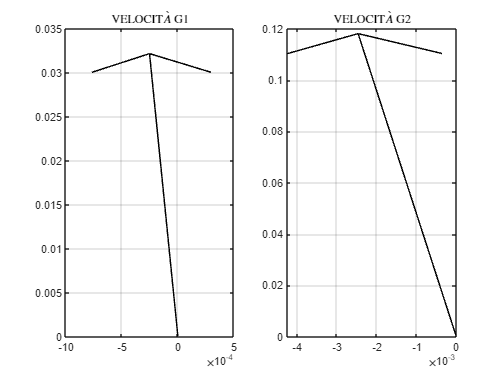

%trovo omega24 (=omega45) per l'adm considerato
omega24teoricoADM=omega24teorico(ADM,1); %[rad/s]
omega24teoricoADMvettore=[0; 0; omega24teoricoADM]; %[rad/s]
omega24puntoteoricoADM=omega24puntoteorico(ADM,1); %[rad/s^2]
omega24puntoteoricoADMvettore=[0; 0; omega24puntoteoricoADM]; %[rad/s^2]
omega45teoricoADM=omega24teoricoADM; %[rad/s]
omega45teoricoADMvettore=omega24teoricoADMvettore; %[rad/s]
omega45puntoteoricoADM=omega24puntoteoricoADM; %[rad/s^2]
omega45puntoteoricoADMvettore=omega24puntoteoricoADMvettore; %[rad/s^2]
vettoreG1_M2ADM=[xG1(ADM,1)-xM2(ADM,1); yG1(ADM,1)-yM2(ADM,1); 0]; %[m]
vettoreG2_M4ADM=[xG2(ADM,1)-xM4(ADM,1); yG2(ADM,1)-yM4(ADM,1); 0]; %[m]
velocitaM4vettoreADM=[xvelocitaM4ADM; yvelocitaM4ADM; 0]; %[m/s]
accelerazioneM4vettoreADM=[xaccelerazioneM4ADM; yaccelerazioneM4ADM; 0]; %[m/s^2]
velocitaM5vettoreADM=[xvelocitaM5ADMteorico; yvelocitaM5ADMteorico; 0]; %[m/s]
accelerazioneM5vettoreADM=[xaccelerazioneM5ADMteorico; yaccelerazioneM5ADMteorico; 0]; %[m/s^2]

%con rivals trovo i vettori velocità di G1 e G2
velocitaG1vettoreADM=cross(omega24teoricoADMvettore,vettoreG1_M2ADM); %[m/s]
velocitaG2vettoreADM=velocitaM4vettoreADM+cross(omega45teoricoADMvettore,vettoreG2_M4ADM); %[m/s]

%ricavo i dati sperimentali nel caso voglia effettuare una verifica sperimentale
xvelocitaG1=zeros(size(t,2),1);
yvelocitaG1=zeros(size(t,2),1);
xvelocitaG2=zeros(size(t,2),1);
yvelocitaG2=zeros(size(t,2),1);
xvelocitaG1(1,1)=0;
yvelocitaG1(1,1)=0;
xvelocitaG2(1,1)=0;
yvelocitaG2(1,1)=0;
xaccelerazioneG1=zeros(size(t,2),1);
yaccelerazioneG1=zeros(size(t,2),1);
xaccelerazioneG2=zeros(size(t,2),1);
yaccelerazioneG2=zeros(size(t,2),1);
xaccelerazioneG1(1,1)=0;
yaccelerazioneG1(1,1)=0;
xaccelerazioneG2(1,1)=0;
yaccelerazioneG2(1,1)=0;
for jj=2:size(t,2)
    xvelocitaG1(jj,1)=(xG1(jj,1)-xG1(jj-1,1))/dt;
    yvelocitaG1(jj,1)=(yG1(jj,1)-yG1(jj-1,1))/dt;
    xvelocitaG2(jj,1)=(xG2(jj,1)-xG2(jj-1,1))/dt;
    yvelocitaG2(jj,1)=(yG2(jj,1)-yG2(jj-1,1))/dt;
    xaccelerazioneG1(jj,1)=(xvelocitaG1(jj,1)-xvelocitaG1(jj-1,1))/dt;
    yaccelerazioneG1(jj,1)=(yvelocitaG1(jj,1)-yvelocitaG1(jj-1,1))/dt;
    xaccelerazioneG2(jj,1)=(xvelocitaG2(jj,1)-xvelocitaG2(jj-1,1))/dt;
    yaccelerazioneG2(jj,1)=(yvelocitaG2(jj,1)-yvelocitaG2(jj-1,1))/dt;
end

figure
subplot(121)
quiver(0,0,velocitaG1vettoreADM(1,1),velocitaG1vettoreADM(2,1), 'k')
grid on
title('VELOCIT$\grave{A}$ G1', 'Interpreter', 'latex')
subplot(122)
quiver(0,0,velocitaG2vettoreADM(1,1),velocitaG2vettoreADM(2,1), 'k')
grid on
title('VELOCIT$\grave{A}$ G2', 'Interpreter', 'latex')

### 4.2 CALCOLO E RAPPRESENTAZIONE DEI VETTORI ACCELERAZIONE DI G1 E G2

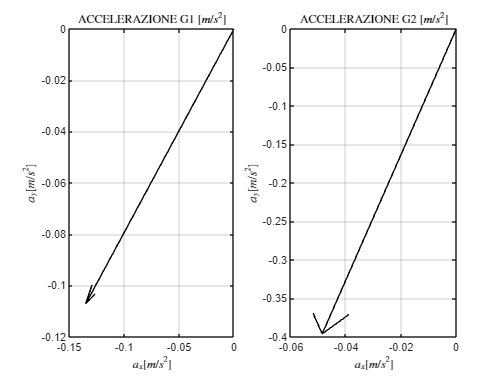

%con il teorema di Rivals per le accelerazioni trovo i vettori accelerazione di G1 e G2
accelerazioneG1vettoreADM=cross(omega24puntoteoricoADMvettore,vettoreG1_M2ADM)-(omega24puntoteoricoADM^2)*vettoreG1_M2ADM; %[m/s^2]
accelerazioneG2vettoreADM=accelerazioneM4vettoreADM+cross(omega45puntoteoricoADMvettore,vettoreG2_M4ADM)-(omega45teoricoADM^2)*vettoreG2_M4ADM; %[m/s^2]

figure
subplot(121)
quiver(0,0,accelerazioneG1vettoreADM(1,1),accelerazioneG1vettoreADM(2,1), 'k')
grid on
title('ACCELERAZIONE G1 $[m/s^2]$', 'Interpreter', 'latex')
xlabel('$a_x [m/s^2]$', 'Interpreter', 'latex')
ylabel('$a_y [m/s^2]$', 'Interpreter', 'latex')
subplot(122)
quiver(0,0,accelerazioneG2vettoreADM(1,1),accelerazioneG2vettoreADM(2,1), 'k')
grid on
title('ACCELERAZIONE G2 $[m/s^2]$', 'Interpreter', 'latex')
xlabel('$a_x [m/s^2]$', 'Interpreter', 'latex')
ylabel('$a_y [m/s^2]$', 'Interpreter', 'latex')

### UTILIZZANDO LE TABELLE ANTROPOMETRICHE CALCOLO LE MASSE DI BRACCIO, AVAMBRACCIO E MANO (anche per un secondo soggetto alto altezza2 cm e pesante peso2 kg, punto 4.6, per il quale calcolo anche le lunghezze di tali segmenti)

massamano=coefficientemassamano*peso; %[kg]
massabraccio=coefficientemassabraccio*peso; %[kg]
massaavambraccio=coefficientemassaavambraccio*peso; %[kg]
massa24=massabraccio; %[kg]
massa45=massaavambraccio+massamano; %[kg]
massamano2=coefficientemassamano*peso2; %[kg]
massabraccio2=coefficientemassabraccio*peso2; %[kg]
massaavambraccio2=coefficientemassaavambraccio*peso2; %[kg]
massa24_2=massabraccio2; %[kg]
massa45_2=massaavambraccio2+massamano2; %[kg]
momentoM2M4_G1=massabraccio*(lunghezzaM2M4(ADM,1)*coefficienterogbraccio)^2; %[kg*m^2]
momentoM4M5_G2=massaavambraccio*(lunghezzaM4M5(ADM,1)*coefficienterogavambracciomano)^2; %[kg*m^2]
momentoM2M4_G1link=massabraccio*linktolerance*(lunghezzaM2M4(ADM,1)*coefficienterogbraccio)^2; %[kg*m^2]
momentoM4M5_G2link=massaavambraccio*linktolerance*(lunghezzaM4M5(ADM,1)*coefficienterogavambracciomano)^2; %[kg*m^2]
momentoM2M4_G1link_2=massabraccio2*linktolerance*(lunghezzaM2M4(ADM,1)*coefficienterogbraccio)^2; %[kg*m^2]
momentoM4M5_G2link_2=massaavambraccio2*linktolerance*(lunghezzaM4M5(ADM,1)*coefficienterogavambracciomano)^2; %[kg*m^2]

### 4.3-4.4 CALCOLO COPPIE NECESSARIE A GARANTIRE L'ADM CONSIDERATO (CON E SENZA SUPPORTO ANTIGRAVITARIO)

%dichiaro le variabili delle due coppie di flessione ed estensione, legate
%tra loro da un fattore che varia a seconda della tipologia del movimento
%(estensione, flessione)
fattorecoppie=0; %[-]
if omega24puntoteoricoADM>0
    fattorecoppie=0.1; %[-]
elseif omega24puntoteoricoADM<0
    fattorecoppie=10; %[-]
end
coppiaflessioneconsupporto=(massa24*(accelerazioneG1vettoreADM')*velocitaG1vettoreADM+massaavambraccio*(accelerazioneG2vettoreADM')*velocitaG2vettoreADM+momentoM2M4_G1*(omega24puntoteoricoADMvettore')*omega24teoricoADMvettore+momentoM4M5_G2*(omega45puntoteoricoADMvettore')*omega45teoricoADMvettore+massamano*(accelerazioneM5vettoreADM')*velocitaM5vettoreADM)/((1-fattorecoppie)*omega24teoricoADM); %[N*m]
coppiaestensioneconsupporto=coppiaflessioneconsupporto*fattorecoppie; %[N*m]
coppiaflessionesenzasupporto=(massa24*(accelerazioneG1vettoreADM')*velocitaG1vettoreADM+massaavambraccio*(accelerazioneG2vettoreADM')*velocitaG2vettoreADM+momentoM2M4_G1*(omega24puntoteoricoADMvettore')*omega24teoricoADMvettore+momentoM4M5_G2*(omega45puntoteoricoADMvettore')*omega45teoricoADMvettore+massamano*(accelerazioneM5vettoreADM')*velocitaM5vettoreADM-massa24*(vettoreg')*velocitaG1vettoreADM-massaavambraccio*(vettoreg')*velocitaG2vettoreADM-massamano*(vettoreg')*velocitaM5vettoreADM)/((1-fattorecoppie)*omega24teoricoADM); %[N*m]
coppiaestensionesenzasupporto=coppiaflessionesenzasupporto*fattorecoppie; %[N*m]
disp(append('Quando è in funzione il supporto antigravitario:', newline, '- la coppia di flessione per l''adm considerato è: ', num2str(coppiaflessioneconsupporto), ' N*m', newline, '- la coppia di estensione è: ', num2str(coppiaestensioneconsupporto), ' N*m', newline, 'Quando non è in funzione il supporto antigravitario:', newline, '- la coppia di flessione per l''adm considerato è: ', num2str(coppiaflessionesenzasupporto), ' N*m', newline, '- la coppia di estensione è: ', num2str(coppiaestensionesenzasupporto), ' N*m'));

Quando è in funzione il supporto antigravitario:
- la coppia di flessione per l'adm considerato è: 0.039002 N*m
- la coppia di estensione è: 0.39002 N*m
Quando non è in funzione il supporto antigravitario:
- la coppia di flessione per l'adm considerato è: 0.81658 N*m
- la coppia di estensione è: 8.1658 N*m


### 4.5 CALCOLO DELLE REAZIONI VINCOLARI SUGLI AGGANCI IN M1 E M2

REAZIONI=[1 0 0 0 1 0 0 0; 
             0 1 0 0 0 1 0 0; 
             0 0 1 0 0 0 1 0; 
             0 0 0 1 0 0 0 -1; 
             0 0 0 0 1 0 -1 0; 
             0 0 0 0 0 1 0 -1; 
             0 0 0 0 0 0 (-1)*lunghezzaM2M4(ADM,1)*abs(sin(angoloM2M4(ADM,1))) lunghezzaM2M4(ADM,1)*abs(cos(angoloM2M4(ADM,1))); 
             0 0 0 0 0 0 lunghezzaM3M4(ADM,1)*abs(sin(angoloM3M4(ADM,1))) lunghezzaM3M4(ADM,1)*abs(cos(angoloM3M4(ADM,1)))];
b=[ 0; 
    0; 
    (-1)*((-1)*massabraccio*linktolerance*xaccelerazioneG1(ADM,1)+(-1)*massaavambraccio*linktolerance*xaccelerazioneG2(ADM,1)+massamano*(-1)*xaccelerazioneM5teorico(ADM,1)); 
    (-1)*((-1)*massabraccio*linktolerance*yaccelerazioneG1(ADM,1)+(-1)*massaavambraccio*linktolerance*yaccelerazioneG2(ADM,1)+massamano*(-1)*yaccelerazioneM5teorico(ADM,1)-g*(massabraccio*linktolerance+massaavambraccio*linktolerance+massamano)); 
    0; 
    0; 
    (-1)*momentoM2M4_G1link*omega24puntoteoricoADM+(-1)*momentoM4M5_G2link*omega45puntoteoricoADM+massabraccio*linktolerance*((-1)*yaccelerazioneG1(ADM,1)*lunghezzaM2G1(ADM,1)*abs(cos(angoloM2M4(ADM,1)))+(-1)*xaccelerazioneG1(ADM,1)*lunghezzaM2G1(ADM,1)*abs(sin(2*pi-angoloM2M4(ADM,1)))-g*lunghezzaM2G1(ADM,1)*abs(cos(angoloM2M4(ADM,1))))+massaavambraccio*linktolerance*(((-1)*yaccelerazioneG2(ADM,1)-g)*abs(lunghezzaM2M4(ADM,1)*cos(angoloM2M4(ADM,1))+lunghezzaM4G2(ADM,1)*cos(angoloM4M5(ADM,1)))+(-1)*xaccelerazioneG2(ADM,1)*abs(lunghezzaM2M4(ADM,1)*sin(2*pi-angoloM2M4(ADM,1))-lunghezzaM4G2(ADM,1)*sin(angoloM4M5(ADM,1))))+massamano*(((-1)*yaccelerazioneM5teorico(ADM,1)-g)*abs(lunghezzaM2M4(ADM,1)*cos(angoloM2M4(ADM,1))+lunghezzaM4M5(ADM,1)*cos(angoloM4M5(ADM,1)))+(-1)*xaccelerazioneM5teorico(ADM,1)*abs(lunghezzaM2M4(ADM,1)*sin(2*pi-angoloM2M4(ADM,1))-lunghezzaM4M5(ADM,1)*sin(angoloM4M5(ADM,1)))); 
    0];
reazioni=linsolve(REAZIONI,b);
H1=reazioni(1,1); %[N]
V1=reazioni(2,1); %[N]
H2=reazioni(3,1); %[N]
V2=reazioni(4,1); %[N]

disp(append('Le reazioni vincolari in M1 e M2 per il soggetto alto ', num2str(altezza*100), ' cm e pesante ', num2str(peso), ' kg sono: ', newline, 'H1 = ', num2str(H1),' N verso sinistra', newline, 'V1 = ', num2str(V1),' N verso l''alto', newline, 'H2 = ', num2str(H2),' N verso destra', newline, 'V2 = ', num2str(V2),' N verso l''alto'));

Le reazioni vincolari in M1 e M2 per il soggetto alto 167 cm e pesante 66 kg sono: 
H1 = -24.1778 N verso sinistra
V1 = 36.8536 N verso l'alto
H2 = -24.3613 N verso destra
V2 = 0.29129 N verso l'alto


### 4.6 CALCOLO DELLE REAZIONI VINCOLARI NEL CASO DI UN SOGGETTO ALTO altezza2 cm E PESANTE peso2 kg

REAZIONI2=[1 0 0 0 1 0 0 0; 
             0 1 0 0 0 1 0 0; 
             0 0 1 0 0 0 1 0; 
             0 0 0 1 0 0 0 -1; 
             0 0 0 0 1 0 -1 0; 
             0 0 0 0 0 1 0 -1; 
             0 0 0 0 0 0 (-1)*lunghezzaM2M4(ADM,1)*abs(sin(angoloM2M4(ADM,1))) lunghezzaM2M4(ADM,1)*abs(cos(angoloM2M4(ADM,1))); 
             0 0 0 0 0 0 lunghezzaM3M4(ADM,1)*abs(sin(angoloM3M4(ADM,1))) lunghezzaM3M4(ADM,1)*abs(cos(angoloM3M4(ADM,1)))];
b2=[ 0; 
    0; 
    (-1)*((-1)*massabraccio2*linktolerance*xaccelerazioneG1(ADM,1)+(-1)*massaavambraccio2*linktolerance*xaccelerazioneG2(ADM,1)+(-1)*massamano2*xaccelerazioneM5teorico(ADM,1)); 
    (-1)*((-1)*massabraccio2*linktolerance*yaccelerazioneG1(ADM,1)+(-1)*massaavambraccio2*linktolerance*yaccelerazioneG2(ADM,1)+(-1)*massamano2*yaccelerazioneM5teorico(ADM,1)-g*(massabraccio2*linktolerance+massaavambraccio2*linktolerance+massamano2)); 
    0; 
    0; 
    (-1)*momentoM2M4_G1link*omega24puntoteoricoADM+(-1)*momentoM4M5_G2link*omega45puntoteoricoADM+massabraccio2*linktolerance*((-1)*yaccelerazioneG1(ADM,1)*lunghezzaM2G1(ADM,1)*abs(cos(angoloM2M4(ADM,1)))+(-1)*xaccelerazioneG1(ADM,1)*lunghezzaM2G1(ADM,1)*abs(sin(2*pi-angoloM2M4(ADM,1)))-g*lunghezzaM2G1(ADM,1)*abs(cos(angoloM2M4(ADM,1))))+massaavambraccio2*linktolerance*(((-1)*yaccelerazioneG2(ADM,1)-g)*abs(lunghezzaM2M4(ADM,1)*cos(angoloM2M4(ADM,1))+lunghezzaM4G2(ADM,1)*cos(angoloM4M5(ADM,1)))+(-1)*xaccelerazioneG2(ADM,1)*abs(lunghezzaM2M4(ADM,1)*sin(2*pi-angoloM2M4(ADM,1))-lunghezzaM4G2(ADM,1)*sin(angoloM4M5(ADM,1))))+massamano*(((-1)*yaccelerazioneM5teorico(ADM,1)-g)*abs(lunghezzaM2M4(ADM,1)*cos(angoloM2M4(ADM,1))+lunghezzaM4M5(ADM,1)*cos(angoloM4M5(ADM,1)))+(-1)*xaccelerazioneM5teorico(ADM,1)*abs(lunghezzaM2M4(ADM,1)*sin(2*pi-angoloM2M4(ADM,1))-lunghezzaM4M5(ADM,1)*sin(angoloM4M5(ADM,1)))); 
    0];
reazioni2=linsolve(REAZIONI2,b2);
H1_2=reazioni2(1,1); %[N]
V1_2=reazioni2(2,1); %[N]
H2_2=reazioni2(3,1); %[N]
V2_2=reazioni2(4,1); %[N]

disp(append('Le reazioni vincolari in M1 e M2 per il soggetto alto ', num2str(altezza2*100), ' cm e pesante ', num2str(peso2), ' kg sono: ', newline, 'H1 = ', num2str(H1_2),' N verso sinistra', newline, 'V1 = ', num2str(V1_2),' N verso l''alto', newline, 'H2 = ', num2str(H2_2),' N verso destra', newline, 'V2 = ', num2str(V2_2),' N verso l''alto'));

Le reazioni vincolari in M1 e M2 per il soggetto alto 190 cm e pesante 90 kg sono: 
H1 = -30.9642 N verso sinistra
V1 = 47.1979 N verso l'alto
H2 = -31.2144 N verso destra
V2 = 3.4542 N verso l'alto


## ----VIBRAZIONI----

### 5.1 CALCOLO DI FREQUENZA PROPRIA E SMORZAMENTO ADIMENSIONALE DEL SISTEMA RISPETTO AL MOTO VERTICALE, CON RAPPRESENTAZIONE DELLA RISPOSTA LIBERA

%creo un vettore tempo esteso per rappresentare meglio i risultati
r=500; %[Ns/m]
m=massamano; %[kg]
testeso=0:0.00001:0.2;
yin=0.005; %[m]
yvin=0; %[m/s]
y0=-m*g/k; %[m]

wn=sqrt(k/m); %[rad/s]
phi=atan(-yvin/(wn*yin)); %[rad]
C=(yin/cos(phi)); %[-]
rc=2*m*wn; %[Ns/m]

%calcolo la frequenza propria
frequenzapropria=wn/(2*pi); %[Hz]
%calcolo la risposta libera non smorzata
yliberanonsmorzata=C*cos(wn*testeso+phi); %[m]

%calcolo lo smorzamento adimensionale
h=r/rc; %[-]
disp(append('La frequenza propria è: ', num2str(frequenzapropria), ' Hz', newline, 'Lo smorzamento adimensionale è: ', num2str(h)));

La frequenza propria è: 282.7662 Hz
Lo smorzamento adimensionale è: 0.35533


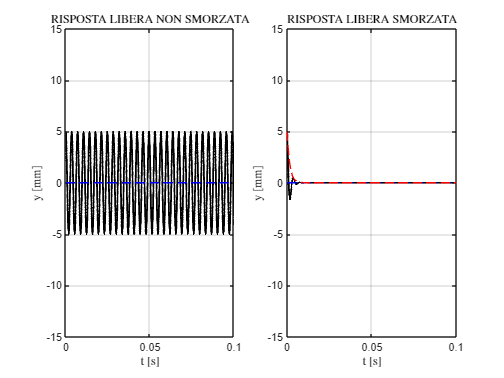

wd=wn*sqrt(1-h^2); %[rad/s]
phid=atan(-yvin/(wd*yin)); %[rad]
Cd=yin/cos(phid); %[-]

%calcolo la risposta libera smorzata
yliberasmorzata=(Cd*cos(wd*testeso+phid)).*(exp(-h*wn*testeso)); %[m]
esponenziale=(exp(-h*wn*testeso)); %esponenziale che delimita la risposta

figure
subplot(121)
plot(testeso,(yliberanonsmorzata+y0)*1000,'LineWidth', 1.5, 'Color', 'black')
grid on
axis([0 0.1 -15 15])
title('RISPOSTA LIBERA NON SMORZATA', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
ylabel('y [mm]', 'Interpreter', 'latex')
hold on
plot([0 0.1],[y0*1000 y0*1000],'b--')
subplot(122)
plot(testeso,(yliberasmorzata+y0)*1000,'LineWidth', 1.5, 'Color', 'black')
grid on
axis([0 0.1 -15 15])
title('RISPOSTA LIBERA SMORZATA', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
ylabel('y [mm]', 'Interpreter', 'latex')
hold on
plot([0 0.1],[y0*1000 y0*1000],'b--')
hold on
plot(testeso, (Cd*esponenziale+y0)*1000, 'r--')

### 5.2 IDENTIFICAZIONE DELLA FUNZIONE DI TRASFERIMENTO E RAPPRESENTAZIONE DELLA RISPOSTA FORZATA

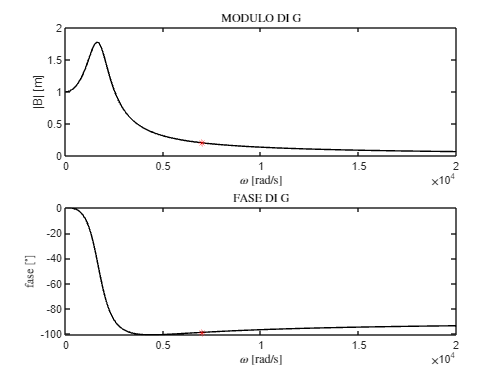

w=0:100:20000;

%calcolo il modulo della forzante
Feq_vett = sqrt(k^2+(w*r).^2)*A;
Feq = sqrt(k^2+(W*r)^2)*A;

%calcolo il modulo e la fase della funzione di trasferimento G tra il feedback e A
G_vett = (k+1i*w*r)./(-m*w.^2+r*1i*w+k); %[-]
G = (k+1i*W*r)/(-m*W^2+r*1i*W+k); %[-]

G_vett_mod = abs(G_vett);
G_mod = abs(G);
G_vett_fase = rad2deg(angle(G_vett));
G_fase = rad2deg(angle(G));

%calcolo la risposta forzata  per w=W
yparticolare_vett=G*A*exp(1i*(W*testeso));
yparticolare=real(yparticolare_vett);
yforzata=yliberasmorzata+yparticolare;

figure
subplot(211)
plot(w,G_vett_mod, 'k')
title('MODULO DI G', 'Interpreter', 'latex')
hold on
plot(W,G_mod,'r*')
xlabel('${\omega}$ [rad/s]', 'Interpreter', 'latex')
ylabel('|B| [m]')
subplot(212)
plot(w,G_vett_fase, 'k')
title('FASE DI G', 'Interpreter', 'latex')
hold on
plot(W,G_fase,'r*')
xlabel('${\omega}$ [rad/s]', 'Interpreter', 'latex')
ylabel('fase $[^{\circ}]$', 'Interpreter', 'latex')

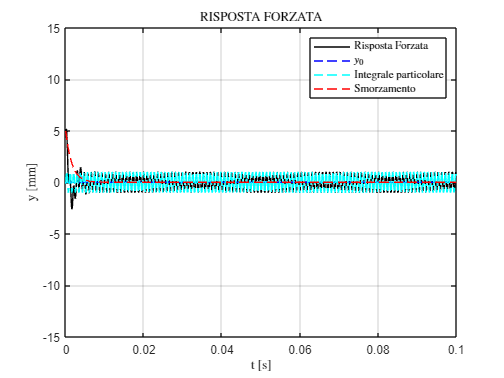

figure
plot(testeso,(y0+yliberasmorzata+yparticolare)*1000, 'k')
grid on
axis([0 0.1 -15 15])
title('RISPOSTA FORZATA', 'Interpreter', 'latex')
xlabel('t [s]', 'Interpreter', 'latex')
ylabel('y [mm]', 'Interpreter', 'latex')
hold on
plot([0 0.1],[y0*1000 y0*1000],'b--')
hold on
plot(testeso, (y0+yparticolare)*1000, 'c--')
hold on
plot(testeso, (Cd*esponenziale+y0)*1000, 'r--')
legend('Risposta Forzata', '$y_{0}$', 'Integrale particolare', 'Smorzamento', 'Interpreter', 'latex')

disp(append('La scelta della pulsazione è buona poichè una frequenza più bassa, come si evince dai diagrammi modulo-fase della funzione di trasferimento, è associata', newline, 'a una minore diminuzione dell''ampiezza del feedback (o addirittura ad una sua amplificazione), e quindi risulta più complicato fornire feedback precisi ', newline, '(servirebbe una precisione maggiore del meccanismo che genera la forzante). Inoltre, frequenze più basse impedirebbero di fornire un ', newline, 'feedback in tempo reale. Al contrario, frequenze più alte permetterebbero una ancora maggiore precisione nel feedback ma, come si evince', newline, 'dai grafici modulo-fase, potrebbero attenuarlo troppo (il modulo della fdt tende infatti a 0 per frequenze maggiori), e quindi esso potrebbe risultare impercettibile ', newline, 'dall''utente'));

La scelta della pulsazione è buona poichè una frequenza più bassa, come si evince dai diagrammi modulo-fase della funzione di trasferimento, è associata
a una minore diminuzione dell'ampiezza del feedback (o addirittura ad una sua amplificazione), e quindi risulta più complicato fornire feedback precisi 
(servirebbe una precisione maggiore del meccanismo che genera la forzante). Inoltre, frequenze più basse impedirebbero di fornire un 
feedback in tempo reale. Al contrario, frequenze più alte permetterebbero una ancora maggiore precisione nel feedback ma, come si evince
dai grafici modulo-fase, potrebbero attenuarlo troppo (il modulo della fdt tende infatti a 0 per frequenze maggiori), e quindi esso potrebbe risultare impercettibile 
dall'utente
